**Real-time Digital Signal Processing Laboratory**

**Soroush Mesforush Mashhad - 810198472**

clc
clear all

Part 1

Here we shall check our filter by generating some sine waves in the passband, transition band and stopband (two waves for each band)

To do so I have created two helper functions, one works as a signal generator and the other is used to create txt files in MATLAB.

Fs = 24000;
freqpass1 = 1200;
freqpass2 = 2200;
freqtrans1 = 3200;
freqtrans2 = 3700;
freqstop1 = 6000;
freqstop2 = 8000;

[Sig1 , ~] = SinewaveGen(freqpass1, Fs);
CreateTXT(Sig1, 'Sinewavepass1.txt')

[Sig2 , ~] = SinewaveGen(freqpass2, Fs);
CreateTXT(Sig2, 'Sinewavepass2.txt')

[Sig3 , ~] = SinewaveGen(freqtrans1, Fs);
CreateTXT(Sig3, 'Sinewavetrans1.txt')

[Sig4 , ~] = SinewaveGen(freqtrans2, Fs);
CreateTXT(Sig4, 'Sinewavetrans2.txt')

[Sig5 , ~] = SinewaveGen(freqstop1, Fs);
CreateTXT(Sig5, 'Sinewavestop1.txt')

[Sig6 , ~] = SinewaveGen(freqstop2, Fs);
CreateTXT(Sig6, 'Sinewavestop2.txt')

Now we go on to plot the filtered sine waves.

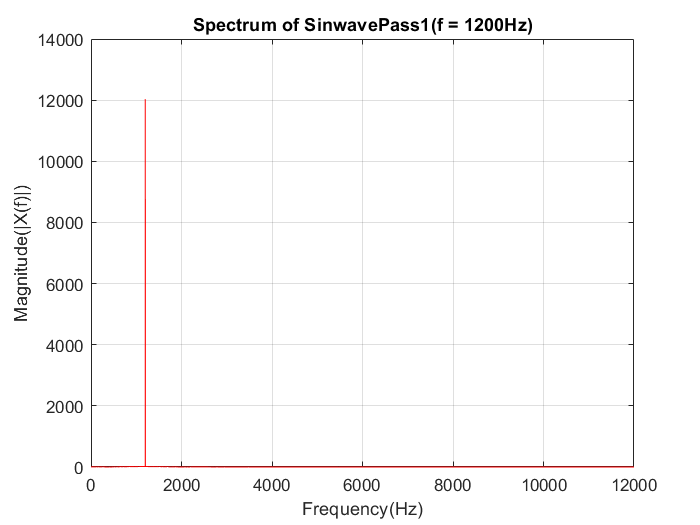

SinewavePass1Fil = ReadTXT('Sinewavepass1Fil.txt');
freq = Fs*(0:(length(SinewavePass1Fil)/2 - 1))/length(SinewavePass1Fil);
SinewavePass1FilF = fftshift(fft(SinewavePass1Fil));
figure(1)
plot(freq,abs(SinewavePass1FilF(end/2+1:end)),'r');
grid on
title('Spectrum of SinwavePass1(f = 1200Hz)');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|X(f)|)');

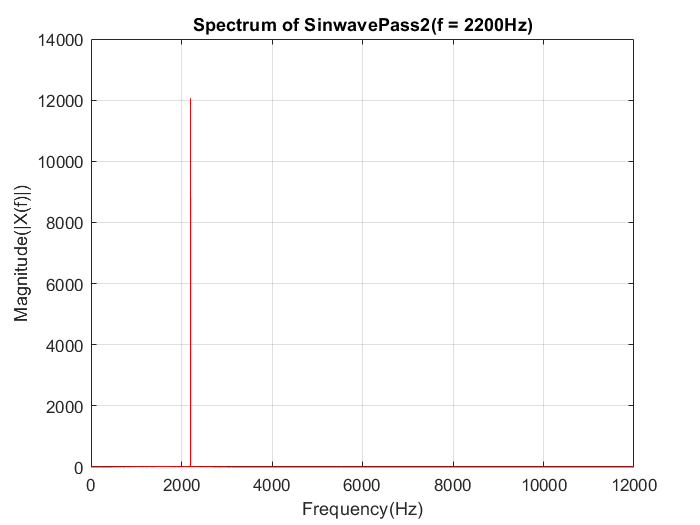


SinewavePass2Fil = ReadTXT('Sinewavepass2Fil.txt');
SinewavePass2FilF = fftshift(fft(SinewavePass2Fil));
figure(2)
plot(freq,abs(SinewavePass2FilF(end/2+1:end)),'r');
grid on
title('Spectrum of SinwavePass2(f = 2200Hz)');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|X(f)|)');

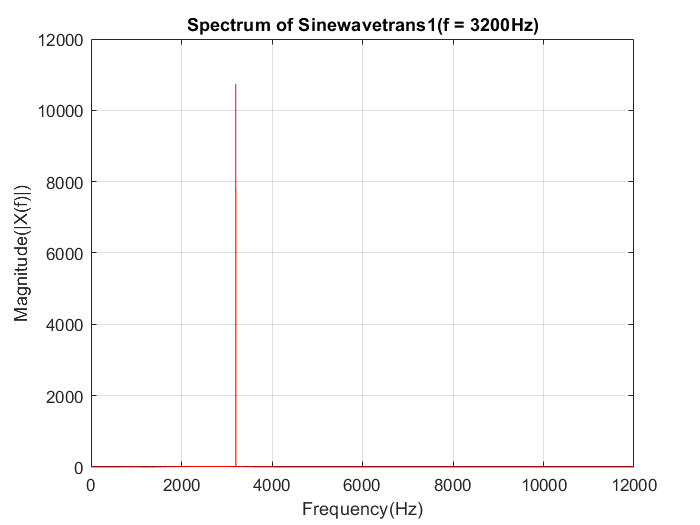


Sinewavetrans1Fil = ReadTXT('Sinewavetrans1Fil.txt');
Sinewavetrans1FilF = fftshift(fft(Sinewavetrans1Fil));
figure(3)
plot(freq,abs(Sinewavetrans1FilF(end/2+1:end)),'r');
grid on
title('Spectrum of Sinewavetrans1(f = 3200Hz)');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|X(f)|)');

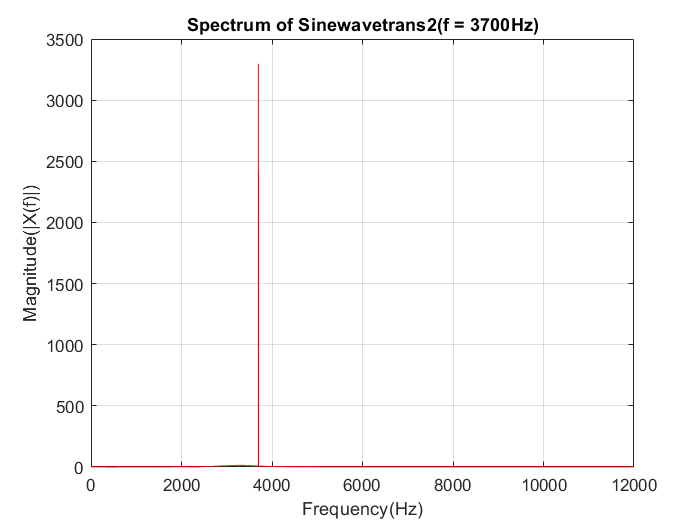


Sinewavetrans2Fil = ReadTXT('Sinewavetrans2Fil.txt');
Sinewavetrans2FilF = fftshift(fft(Sinewavetrans2Fil));
figure(4)
plot(freq,abs(Sinewavetrans2FilF(end/2+1:end)),'r');
grid on
title('Spectrum of Sinewavetrans2(f = 3700Hz)');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|X(f)|)');

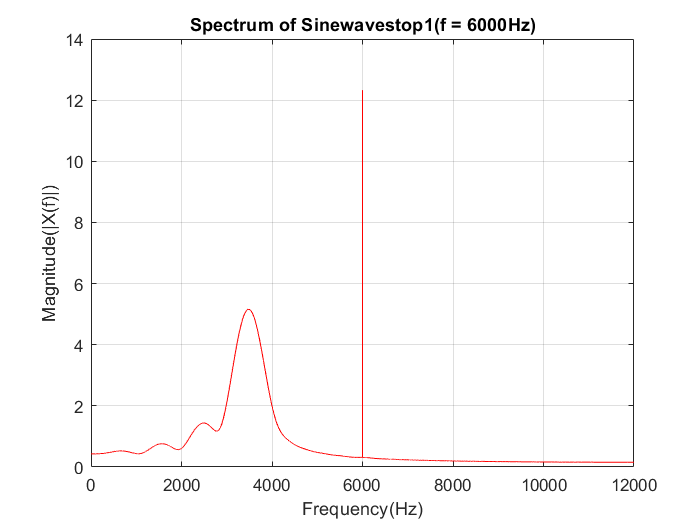


Sinewavestop1Fil = ReadTXT('Sinewavestop1Fil.txt');
Sinewavestop1FilF = fftshift(fft(Sinewavestop1Fil));
figure(5)
plot(freq,abs(Sinewavestop1FilF(end/2+1:end)),'r');
grid on
title('Spectrum of Sinewavestop1(f = 6000Hz)');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|X(f)|)');

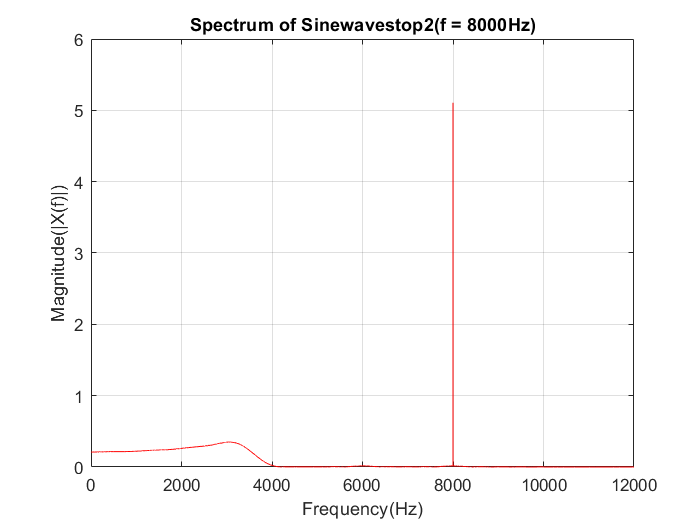


Sinewavestop2Fil = ReadTXT('Sinewavestop2Fil.txt');
Sinewavestop2FilF = fftshift(fft(Sinewavestop2Fil));
figure(6)
plot(freq,abs(Sinewavestop2FilF(end/2+1:end)),'r');
grid on
title('Spectrum of Sinewavestop2(f = 8000Hz)');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|X(f)|)');

Part 2

Here we shall create a white noise and perform the same analysis as the sine wave with our C program.

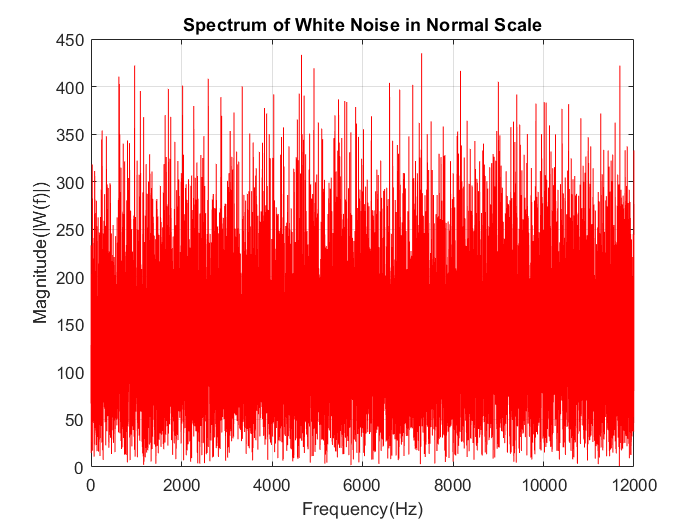

WhiteNoise = wgn(Fs,1,0);
WhiteNoiseF = fftshift(fft(WhiteNoise));
figure(7)
plot(freq,abs(WhiteNoiseF(end/2+1:end)),'r');
grid on
title('Spectrum of White Noise in Normal Scale');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|W(f)|)');

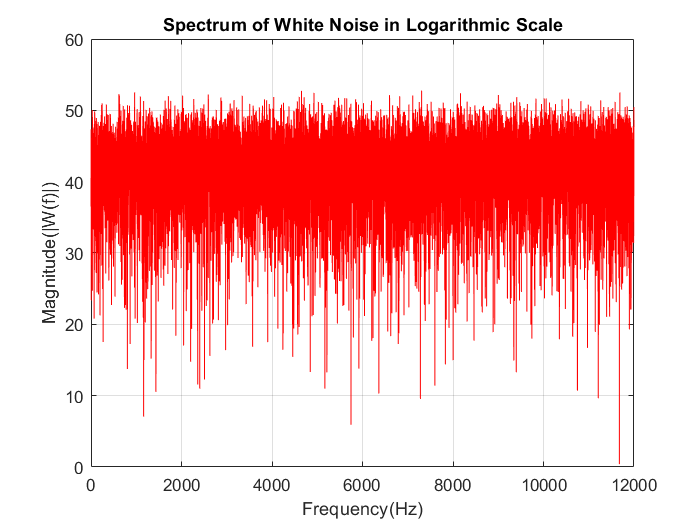

figure(8)
plot(freq,db(abs(WhiteNoiseF(end/2+1:end))),'r');
grid on
title('Spectrum of White Noise in Logarithmic Scale');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|W(f)|)');

CreateTXT(WhiteNoise, 'WhiteNoise.txt')

Now we go on to plot the white noise

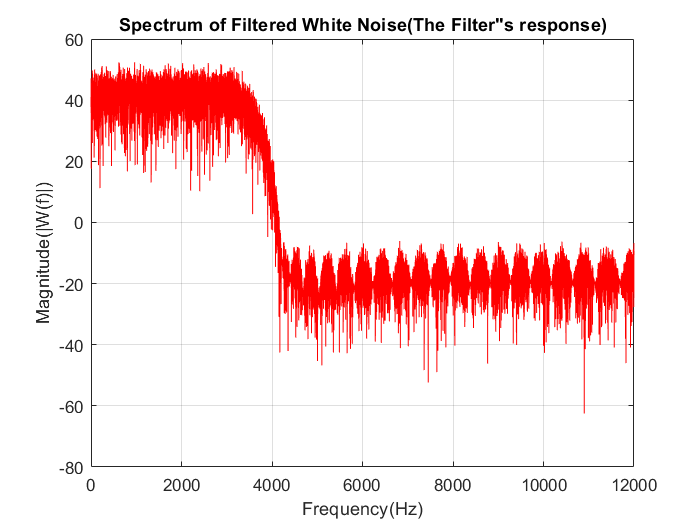

WhiteNoiseFil = ReadTXT('WhiteNoiseFil.txt');
WhiteNoiseFilF = fftshift(fft(WhiteNoiseFil));
figure(7)
plot(freq,db(abs(WhiteNoiseFilF(end/2+1:end))),'r');
grid on
title('Spectrum of Filtered White Noise(The Filter"s response)');
xlabel('Frequency(Hz)');
ylabel('Magnitude(|W(f)|)');